# EULER

clc
syms x

## Initial Conditions

naco = input("1) Caso A \n 2) Caso B \n 3) Caso C \n [ENTER] para continuar \n");
op=input("¿Que caso desea?");
y0 = 70.0;
vy0 = -15; % Va a la derecha
g = -9.81;
c1= 40;




l=.175;

w=0.3657;
% AÑADIR EL TIEMPO FINAL DE CADA CASO

## Time and stepSize

tf = 10; % 'Cause its really fast
N = 10000; % 'Cause it's Euler hahahahah
h = tf / N*200;

## Vector Arrays


y = zeros(N,1); y(1) = y0; % Added the initial condition

vy = zeros(N,1); vy(1) = vy0; % Added the initial condition

t = zeros(N,1); t(1) = 0.0; % Simulation starts at 0 s

## Diff equations

% Primera Fase
dy =@ (t, vy) g*t + vy;
dvy =@ (t, vy) (g*t.^2)/2 + vy*t;
ac = @ (t) g;




## **Menu**

    ymax=70;
    
    if op==1
        vy0=input("¿Con que velocidad sale el trampolin?");
        vy = zeros(N,1); vy(1) = vy0;
        disp(vy0);
        td=((-vy0)/g);
        td = ceil(td);
        t(1)= 0;
        n=1;
        while vy(n)>0
            vy(n+1)=vy(n)+g*h; 
            y(n+1)=y(n)+vy(n)*h+0.5*t(n)*g;
            t(n+1)=t(n)+1;
            ymax = y(n);
           
            n=n+1;
        end
        
       if vy0==0
           n=2;
       end
       
        while vy(n-1)<(-vy0)
            
            vy(n+1)=vy(n)+g*h;
            y(n+1)=y(n)+vy(n)*h+0.5*t(n)*g;
            t(n+1)=t(n)+1;
            
            n=n+1;
            
        end  
        
        if vy0==0
           n=1;
        end
        tdn=n;
        disp(tdn);
        disp(vy(tdn));
        
    end
    
    if op==2
        vy0=input("Con que velocidad se lanza de clavado?");
        tdn=1;
        vy(1)=-vy0;
    end
    
    if op==3
        
        vy0=0;
        tdn=1;
        vy(1)=vy0;
    end


## Euler method

    n=tdn;
    disp("hola");

hola


    disp(vy(n));

     0



    while y(n)>=40
       
        t(n+1) = t(n)+h;
        %First step calculate the constants k's in positions
       
        k1=h*dy(t(n), vy(n));
        y(n+1)=y(n)+k1;
        
        
        % Calculate velocity k's 
        k1=h*ac(t);
        vy(n+1)=vy(n)+k1;
        n=n+1;
        f=n;
        
    end
    disp("Velocidad inicial")

Velocidad inicial


    disp(vy0)

     0



    disp("Tiempo en alcanzar la longitud natural de la cuerda: ")

Tiempo en alcanzar la longitud natural de la cuerda: 


    disp(t(n))

    2.0000



    disp("Tiempo en alcanzar la longitud natural de la cuerda: ")

Tiempo en alcanzar la longitud natural de la cuerda: 


    disp(t(n))

    2.0000



    disp("Velocidad final")

Velocidad final


    disp(vy(n))

  -19.6200



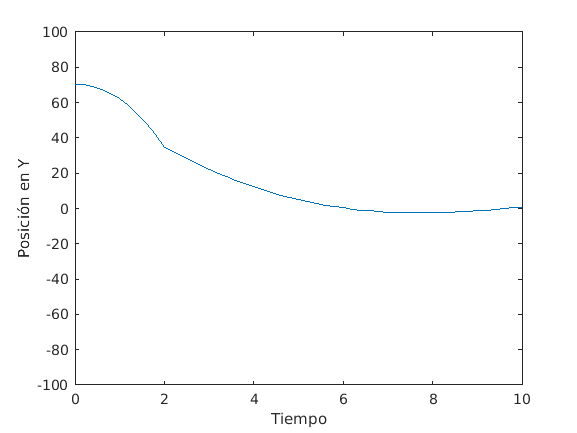

    if op==1
        o=-10;
    else 
        o=-vy(n);
    end
   
    c2=-(o+7)/sqrt(0.1031188);
    
    % Segunda fase

    y2 = @(x) (exp(-l*x)*(c1*cos(sqrt(w.^2-l.^2)*x)+c2*sin(w.^2-l.^2)*x));
    y2p = (exp(-l*x)*(c1*cos(sqrt(w.^2-l.^2)*x)+c2*sin(w.^2-l.^2)*x));
    vy2p=diff(y2p);
    vy2=char(vy2p);
    vy2=strcat('@(x)',vy2);
    vy2=str2func(vy2);
    
    
    ac2=diff(vy2p);
    ac2=char(ac2);
    ac2=strcat('@(x)',ac2);
    ac2=str2func(ac2);
    
    for n=n:N-1
        
        t(n+1) = t(n)+h;
        %First step calculate the constants k's in positions
       
        k1=h*vy2(t(n));
        y(n+1)=y(n)+k1;
        
        
        % Calculate velocity k's 
        if op==1
            q=t(n)-10;
        else
            q=t(n);
        end
   
        k1=h*(ac2(q));
        vy(n+1)=vy(n)+k1;
    end
    

    
    z = 38;
    yplot=y;
    yplot(yplot==0)=nan;
    tplot=t;
    tplot(yplot==0)=nan;
    plot(tplot,yplot); 
    xlabel('Tiempo') 
    ylabel('Posición en Y') 
    tmax=t(n);
    ymax=ceil(ymax + 5);
    ylim([-100 100]);
    xlim([0 10]);

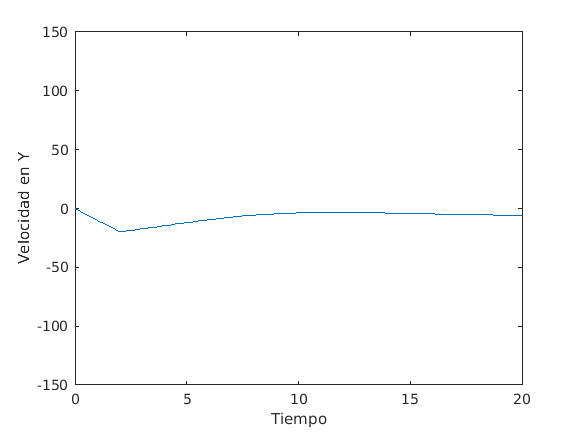

    
    
    vyplot=vy;
    vyplot(vyplot==0)=nan;
    vyplot(1)=vy0;
    if op==2
        vyplot(1)=-vy0;
    end
    if (op==3)
        vyplot(1)=0;
        
    end
    
    plot(tplot,vyplot); 
    xlim([0 20]);
    ylim([-150 150]);
    xlabel('Tiempo') 
    ylabel('Velocidad en Y') 